close all; clear all

## **Parameter definition **

x = [-2 2] 

y=-4x^3 +6x^2-2x-1 + error 

theta_true = [-4 6 -2 -1] 

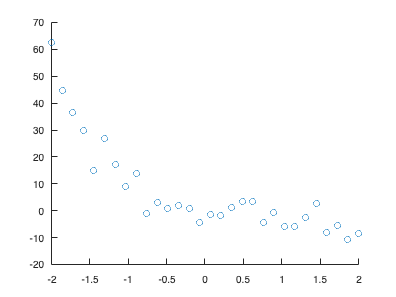

x = linspace(-2,2,30);
m=length(x);
epsi=4*randn(1,m);
y = -4*x.^3+6*x.^2-2*x-1+epsi;
scatter(x,y)

## **Polynomial fitting using MATLAB-embedded Functions**

- polyfit,

- polyval

hold on
orderr=[1 3 5 7 9];
for i=1:length(orderr)
    [p,S] = polyfit(x,y,orderr(i));
    f1=polyval(p,x);
    residualss(i)=S.normr
    [coeff_1,residuals] = my_poly_n(x,y,orderr(i));
   f2=polyval(coeff_1,x);
   err_=norm(f1-f2)
   residuals_cal(i)=residuals
    plot(x,f1,'LineWidth',2)
end

residualss = 54.3564

err_ = 3.3460e-14

residuals_cal = 54.3564

residualss =    54.3564   21.8356


err_ = 3.1766e-14

residuals_cal =    54.3564   21.8356


residualss =    54.3564   21.8356   20.9789


err_ = 5.2135e-14

residuals_cal =    54.3564   21.8356   20.9789


residualss =    54.3564   21.8356   20.9789   19.6185


err_ = 8.9113e-12

residuals_cal =    54.3564   21.8356   20.9789   19.6185


residualss =    54.3564   21.8356   20.9789   19.6185   18.5969


err_ = 3.5755e-11

residuals_cal =    54.3564   21.8356   20.9789   19.6185   18.5969


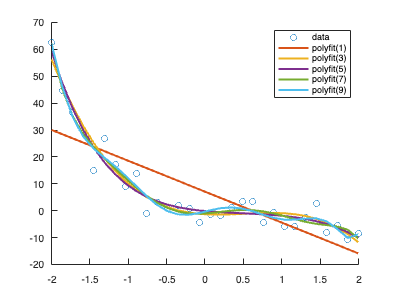

legend('data','polyfit(1)','polyfit(3)','polyfit(5)','polyfit(7)',['polyfit(',num2str(orderr(end)),')'])

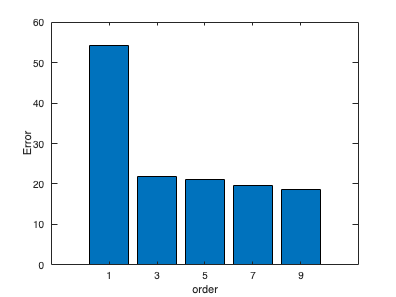


figure
bar(orderr,residualss)
xlabel('order'); ylabel('Error')

## **Polynomial coefficients Estimation Function  **

function [coeff,residuals] = my_poly_n(input,output,order)
m=length(input);
Regressor =zeros(m,order+1);
for i=1:m
    for j = 1:order+1
        Regressor(i,j)= 1*input(i)^(order+1-j);
    end
end
coeff = (Regressor.'*Regressor)\Regressor.'*output.'; % Regressor/output
residuals= sqrt((output.'-Regressor*coeff)'*(output.'-Regressor*coeff));
end